load HCVEgyptData.mat
disp(HCV)

    Age    Gender    BMI    Fever    NauseaVomting    Headache    Diarrhea    Fatiguegeneralizedboneache    Jaundice    Epigastricpain     WBC        RBC        HGB       Plat       AST1    ALT1    ALT4    ALT12    ALT24    ALT36    ALT48    ALTafter24w     RNABase         RNA4         RNA12         RNAEOT        RNAEF       BaselinehistologicalGrading    Baselinehistologicalstaging
    ___    ______    ___    _____    ________

class(HCV)

ans = 'table'

size(HCV)

ans =         1385          29


sum(sum(ismissing(HCV)))

ans = 0

HCV_array=table2array(HCV);

# Check distribution

HCV_array=normalize(HCV_array,'range')

HCV_array =     0.8276         0    1.0000    1.0000         0         0         0    1.0000    1.0000    1.0000    0.4867    0.3597    0.8000    0.1433    0.6742    0.5056    0.1461    0.7865    0.4719         0         0         0    0.5456    0.5280    0.0772         0         0    0.7692    0.3333
    0.4828         0    0.5385         0    1.0000    1.0000         0    1.0000    1.0000         0    1.0000    0.5100         0    0.2724    0.5843    0.9438    0.6292    0.4045    0.8315    0.4228    0.9593    0.9750    0.0338    0.4482    0.1707    0.4166    0.0384    0.0769    0.3333
    0.8621         0    0.8462    1.0000    1.0000    1.0000    1.0000         0         0         0    0.1303    0.6695    0.4000    0.4384    0.8315    0.1124    0.6292    0.7640    0.8652         0         0         0    0.4755    0.5503         0    0.9103    0.6896    0.0769    1.0000
    0.5862    1.0000    0.8462         0    1.0000         0    1.0000         0    1.0000         0    0.3841    0

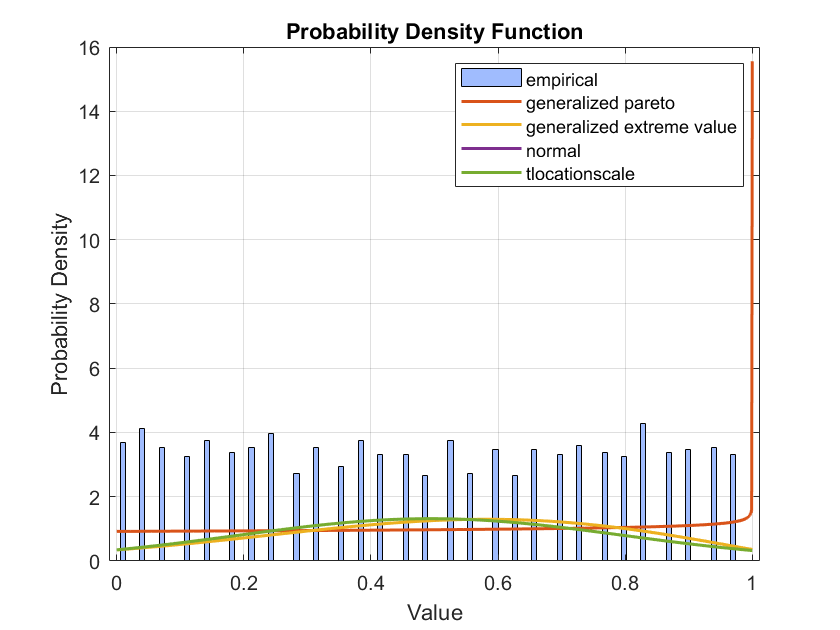

h1 = figure();
set(h1, 'Visible', 'off')
[D, PD] = allfitdist(HCV_array(:,1), 'PDF');

D(1)

ans = struct with fields:
            DistName: 'generalized pareto'
               NLogL: -95.7222
                 BIC: -169.7439
                 AIC: -185.4443
                AICc: -185.4269
          ParamNames: {'k'  'sigma'  'theta'}
    ParamDescription: {'shape'  'scale'  'threshold'}
              Params: [-1.0851 1.0851 -2.2204e-15]
             Paramci: [2×3 double]
            ParamCov: [3×3 double]
             Support: [1×1 struct]


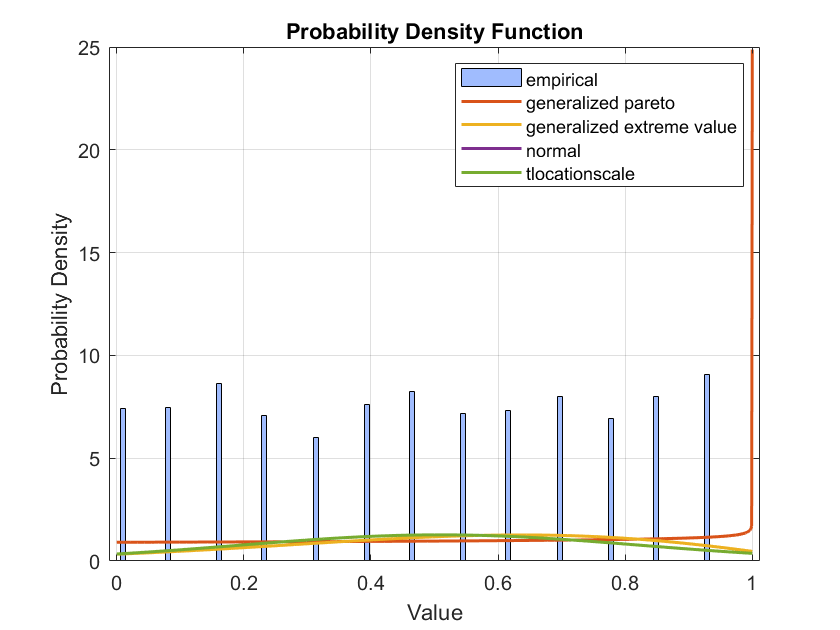

[D, PD] = allfitdist(HCV_array(:,3), 'PDF');

D(1)

ans = struct with fields:
            DistName: 'generalized pareto'
               NLogL: -299.9153
                 BIC: -578.1303
                 AIC: -593.8307
                AICc: -593.8133
          ParamNames: {'k'  'sigma'  'theta'}
    ParamDescription: {'shape'  'scale'  'threshold'}
              Params: [-1.0990 1.0990 -2.2204e-15]
             Paramci: [2×3 double]
            ParamCov: [3×3 double]
             Support: [1×1 struct]


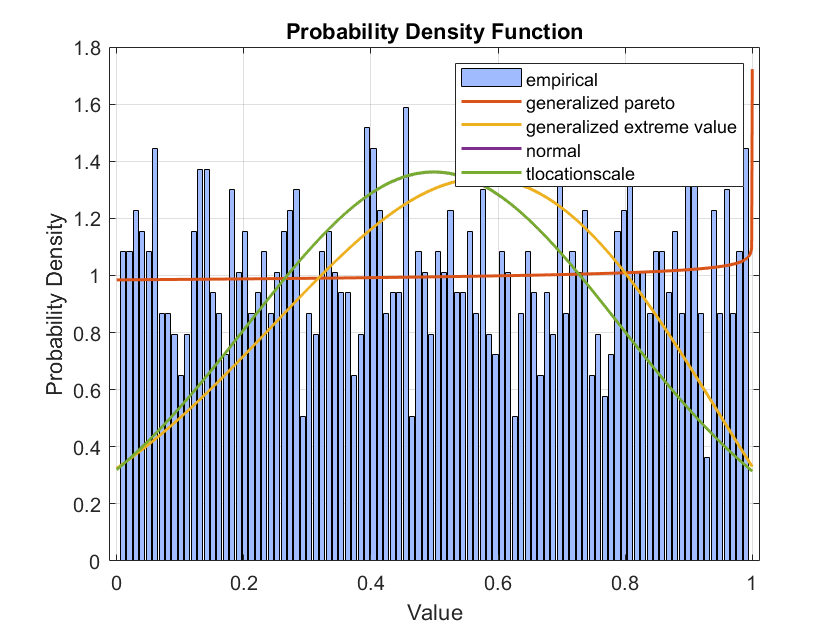

[D, PD] = allfitdist(HCV_array(:,11), 'PDF');

D(1)

ans = struct with fields:
            DistName: 'generalized pareto'
               NLogL: -0.5405
                 BIC: 20.6193
                 AIC: 4.9190
                AICc: 4.9363
          ParamNames: {'k'  'sigma'  'theta'}
    ParamDescription: {'shape'  'scale'  'threshold'}
              Params: [-1.0158 1.0158 -2.2204e-15]
             Paramci: [2×3 double]
            ParamCov: [3×3 double]
             Support: [1×1 struct]


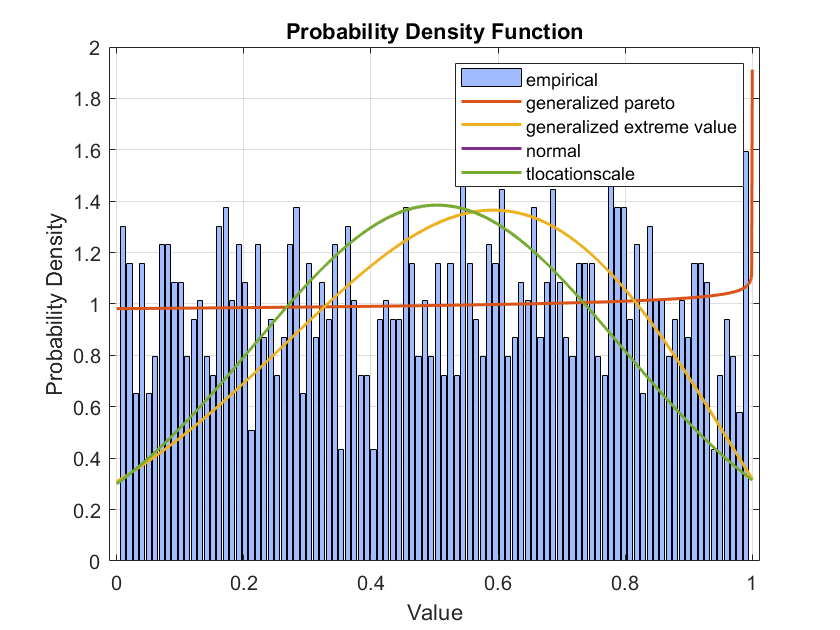

[D, PD] = allfitdist(HCV_array(:,12), 'PDF');

D(1)

ans = struct with fields:
            DistName: 'generalized pareto'
               NLogL: -0.5917
                 BIC: 20.5170
                 AIC: 4.8167
                AICc: 4.8340
          ParamNames: {'k'  'sigma'  'theta'}
    ParamDescription: {'shape'  'scale'  'threshold'}
              Params: [-1.0185 1.0185 -2.2204e-15]
             Paramci: [2×3 double]
            ParamCov: [3×3 double]
             Support: [1×1 struct]


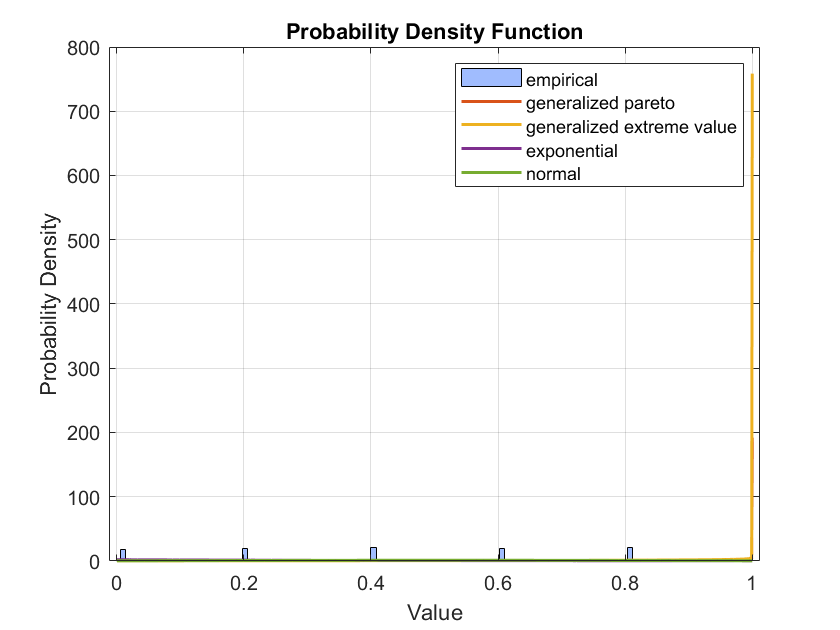

[D, PD] = allfitdist(HCV_array(:,13), 'PDF');

D(1)

ans = struct with fields:
            DistName: 'generalized pareto'
               NLogL: -1.2871e+03
                 BIC: -2.5525e+03
                 AIC: -2.5682e+03
                AICc: -2.5682e+03
          ParamNames: {'k'  'sigma'  'theta'}
    ParamDescription: {'shape'  'scale'  'threshold'}
              Params: [-1.1730 1.1730 -2.2204e-15]
             Paramci: [2×3 double]
            ParamCov: [3×3 double]
             Support: [1×1 struct]


ans = 'generalized pareto'

HCV_array=normalize(HCV_array,'range');

HCV_array =     0.8276         0    1.0000    1.0000         0         0         0    1.0000    1.0000    1.0000    0.4867    0.3597    0.8000    0.1433    0.6742    0.5056    0.1461    0.7865    0.4719         0         0         0    0.5456    0.5280    0.0772         0         0    0.7692    0.3333
    0.4828         0    0.5385         0    1.0000    1.0000         0    1.0000    1.0000         0    1.0000    0.5100         0    0.2724    0.5843    0.9438    0.6292    0.4045    0.8315    0.4228    0.9593    0.9750    0.0338    0.4482    0.1707    0.4166    0.0384    0.0769    0.3333
    0.8621         0    0.8462    1.0000    1.0000    1.0000    1.0000         0         0         0    0.1303    0.6695    0.4000    0.4384    0.8315    0.1124    0.6292    0.7640    0.8652         0         0         0    0.4755    0.5503         0    0.9103    0.6896    0.0769    1.0000
    0.5862    1.0000    0.8462         0    1.0000         0    1.0000         0    1.0000         0    0.3841    0

s=string.empty;
for i=[1,3,11:27]
    [D, PD] = allfitdist(HCV_array(:,1), 'PDF');
    s(i)=D(1).DistName;
end

s

s = 1×27 string array
    "generalized pareto"    <missing>    "generalized pareto"    <missing>    <missing>    <missing>    <missing>    <missing>    <missing>    <missing>    "generalized pareto"    "generalized pareto"    "generalized pareto"    "generalized pareto"    "generalized pareto"    "generalized pareto"    "generalized pareto"    "generalized pareto"    "generalized pareto"    "generalized pareto"    "generalized pareto"    "generalized pareto"    "generalized pareto"    "generalized pareto"    "generalized pareto"    "generalized pareto"    "generalized pareto"


% most generalized pareto

x=HCV.HGB;
g=HCV.Gender;
min(x)

ans = 10

max(x)

ans = 15

pd = fitdist(x,'Normal')

pd =   NormalDistribution

  Normal distribution
       mu = 12.5877   [12.4974, 12.678]
    sigma = 1.71351   [1.65199, 1.77982]


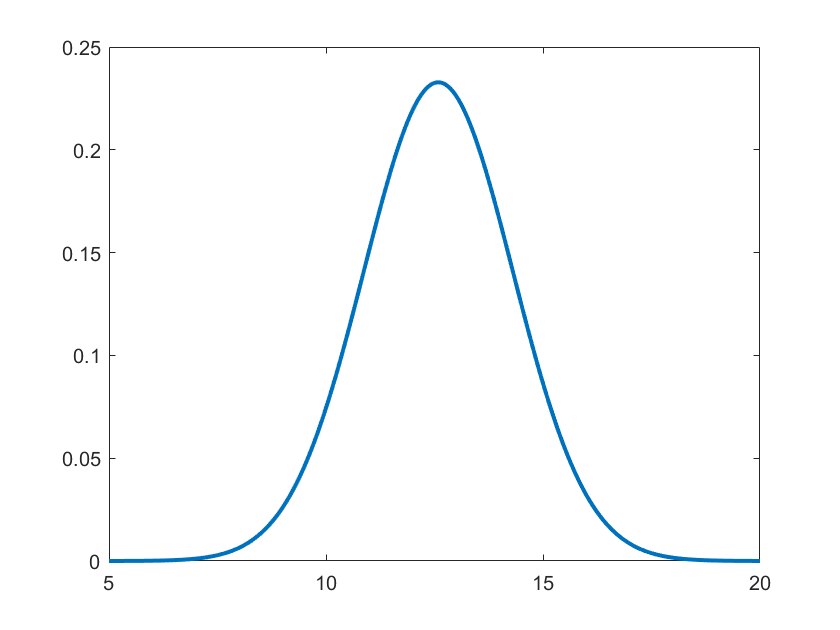

x_values = 5:0.01:20;
y = pdf(pd,x_values);
figure
plot(x_values,y,'LineWidth',2)

[pdca, gn,gl] = fitdist(x,'Normal','By',g)

pdca = 1×2 cell array
    {1×1 prob.NormalDistribution}    {1×1 prob.NormalDistribution}


gn = 2×1 cell array
    {'1'}
    {'2'}


gl = 2×1 cell array
    {'1'}
    {'2'}


female = pdca{2}  % Distribution for females

female =   NormalDistribution

  Normal distribution
       mu = 12.5855   [12.4551, 12.716]
    sigma = 1.73015   [1.6427, 1.8275]


male = pdca{1}  % Distribution for males

male =   NormalDistribution

  Normal distribution
       mu = 12.5898   [12.4644, 12.7152]
    sigma = 1.69863   [1.61447, 1.79211]


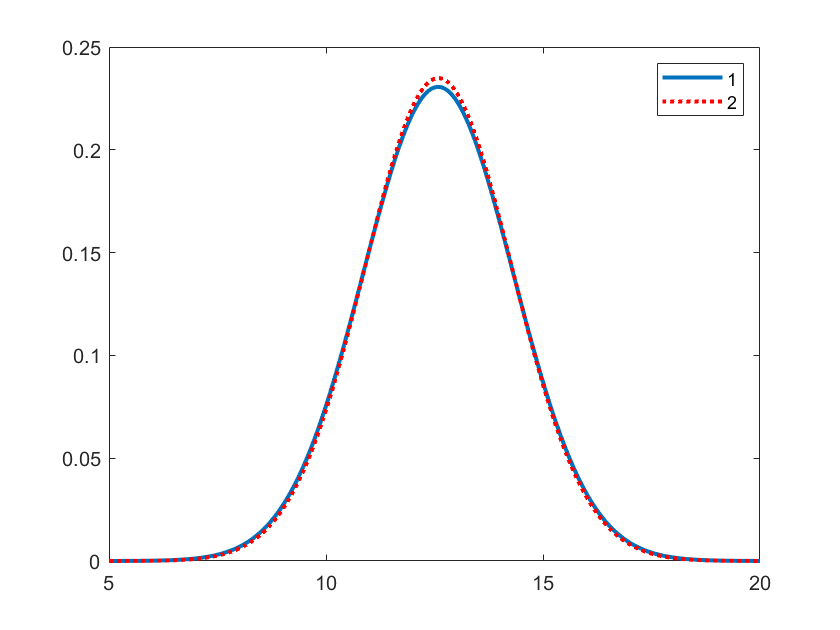

x_values = 5:0.01:20;
femalepdf = pdf(female,x_values);
malepdf = pdf(male,x_values);
figure
plot(x_values,femalepdf,'LineWidth',2)
hold on
plot(x_values,malepdf,'Color','r','LineStyle',':','LineWidth',2)
legend(gn,'Location','NorthEast')
hold off

%Null hypothesis : Data has ..... distribution
x=HCV_array(:,1)

x =     0.8276
    0.4828
    0.8621
    0.5862
    0.9310
    0.8966
    0.3448
    0.5517
    0.4138
    0.4483


f=gpfit(x)

Error using gpfit (line 46)
The data in X must be positive.

pd = fitdist(x,'GeneralizedPareto');
[h p] = chi2gof(x,'CDF',pd)